# Create Virtual Dataset from Datasets of Varying Sizes

Create an HDF5 Virtual Dataset from datasets of varying sizes and with mismatching group and dataset names. The elevation data in the three datasets is generated from the MATLAB `peaks` function. 

Use three datasets containing elevation data to reconstruct a larger, more complete topographical map. The three datasets are disjoint, meaning spatial data is missing along one or more of their shared dimensions, and they vary in shape and size. 

Reconstruct the topographical profile with the three disjoint datasets. The sampling points from the three datasets are overlayed on the topographical profile according to their geospatial coordinates. In both plots, the x and y axes represent longitudes and latitudes, respectively, with latitudes increasing in the y-direction. 

      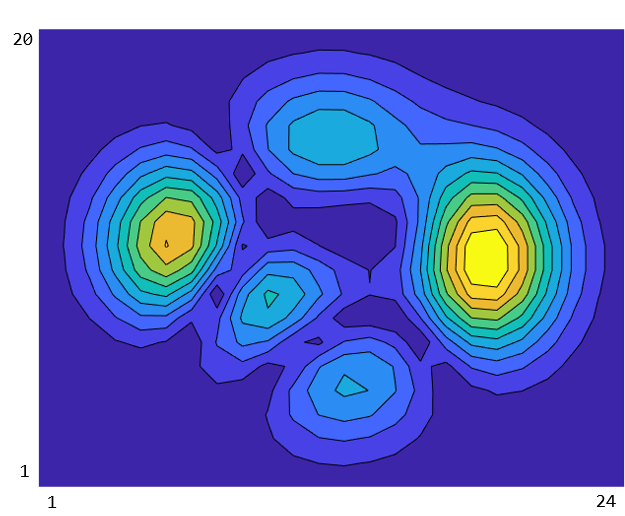  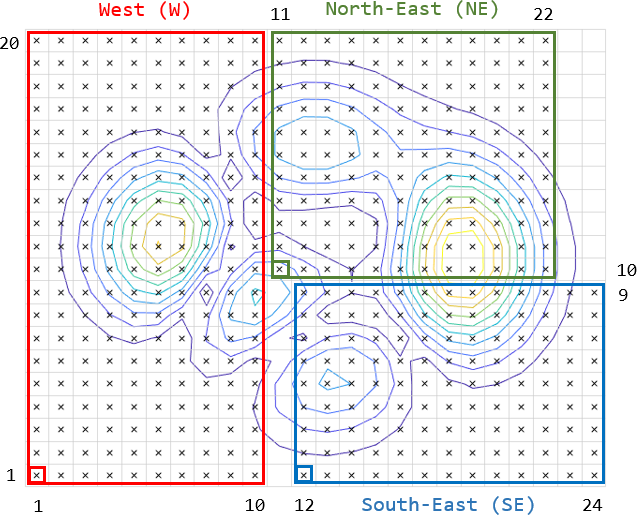

Display information on the three datasets in the files `data_W.h5`, `data_NE.h5`, `data_SE.h5`. The `h5disp` function displays information about the datasets, including their names, datatypes, dimensions, and groups to which they belong.

h5disp("data_W.h5")
h5disp("data_NE.h5")
h5disp("data_SE.h5")

Create a dataspace and creation property list for the Virtual Dataset. Then, map each dataset to the virtual dataspace using C-style dimensions ordering and zero-based indexing. 

For instance, the lower-left corner of the data block for the North-East region corresponds to MATLAB indices `[10 11]`. To convert these indices to C-style ordered, zero-based indices, flip the indices `[10 11]` and subtract the value `1`. The resulting start indices are `[10 9]`. 

% Define the fill value and specify the file access property list identifier.
fillValue = NaN;
faplID = H5P.create('H5P_FILE_ACCESS');

% Create the file for the Virtual Dataset.
vdsFileID = H5F.create('data_VDS.h5','H5F_ACC_TRUNC','H5P_DEFAULT',faplID);

% Define the datatype and dataspace.
datatypeID = H5T.copy('H5T_NATIVE_DOUBLE');
vdsDataspaceID = H5S.create_simple(2,[24 20],[]);

% Initialize Virtual Dataset creation property list with virtual layout and fill value.
vdsDcplID = H5P.create('H5P_DATASET_CREATE');
H5P.set_layout(vdsDcplID,'H5D_VIRTUAL');
H5P.set_fill_value(vdsDcplID,datatypeID,fillValue);

% Perform full dataset mapping for three individual source datasets.

% Map '/data/elevation' from data_W.h5 to the Virtual Dataset.
srcDataspaceID_W = H5S.create_simple(2,[10 20],[]);
H5S.select_hyperslab(vdsDataspaceID,'H5S_SELECT_SET',[0 0],[],[],[10 20]);
H5P.set_virtual(vdsDcplID, vdsDataspaceID,'data_W.h5','/data/elevation',srcDataspaceID_W);

% Map '/z' from data_NE.h5 to the Virtual Dataset.
srcDataspaceID_NE = H5S.create_simple(2,[12 11],[]);
H5S.select_hyperslab(vdsDataspaceID,'H5S_SELECT_SET',[10 9],[],[],[12 11]);
H5P.set_virtual(vdsDcplID,vdsDataspaceID,'data_NE.h5','/z',srcDataspaceID_NE);

% Map '/Elev' from data_SE.h5 to the Virtual Dataset.
srcDataspaceID_SE = H5S.create_simple(2,[13 9],[]);
H5S.select_hyperslab(vdsDataspaceID,'H5S_SELECT_SET',[11 0],[],[],[13 9]);
H5P.set_virtual(vdsDcplID,vdsDataspaceID,'data_SE.h5','/Elev',srcDataspaceID_SE);

Create the HDF5 file and the Virtual Dataset `/elevation`, and then close all open resources.

% Call H5D.create using the defined properties.
vdsDatasetID = H5D.create(vdsFileID,'/elevation',datatypeID,vdsDataspaceID, ...
                          'H5P_DEFAULT',vdsDcplID,'H5P_DEFAULT');

% Close open resources.
H5D.close(vdsDatasetID);
H5S.close(srcDataspaceID_SE);
H5S.close(srcDataspaceID_NE);
H5S.close(srcDataspaceID_W);
H5P.close(vdsDcplID);
H5S.close(vdsDataspaceID);
H5T.close(datatypeID);
H5F.close(vdsFileID);
H5P.close(faplID);

Read the Virtual Dataset and plot it. 

The resulting plot is similar to the original plot of the topographical map, except for the areas where data is missing due to the disjoint datasets.

% Read elevations using the low-level interface.
vdsFileID = H5F.open('data_VDS.h5','H5F_ACC_RDONLY','H5P_DEFAULT');
vdsDatasetID = H5D.open(vdsFileID,'/elevation','H5P_DEFAULT');
elevation = H5D.read(vdsDatasetID,'H5ML_DEFAULT','H5S_ALL','H5S_ALL','H5P_DEFAULT');
H5D.close(vdsDatasetID);
H5F.close(vdsFileID);
contourf(elevation,10);

Display the contents of the Virtual Dataset file.

h5disp('data_VDS.h5')

You can perform I/O operations on the Virtual Dataset. For instance, read a hyperslab of data from the `/elevation` dataset using the `h5read` function in the high-level interface.

sample = h5read('data_VDS.h5','/elevation',[1 1],[5 6],[4 4])

*Copyright 2021 The MathWorks, Inc.*